# Min variance Allocation of weights to paths within clusters Test File  

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 26/10/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

## **Purpose**

*****

*****

**NOTE: **To maximise the efficiency of clustering algorithms, avoid running the graph-generating code. This ensures that the JIT (Just-In-Time) compiler dedicates its efforts to optimizing the clustering code. Although JIT compilation introduces initial overhead during code execution, its primary advantage is optimizing frequently executed sections of the code. The JIT compiler selectively compiles 'hotspots' based on runtime profiling information, adapting the code to the runtime environment and enhancing subsequent executions.

**Estimate K, the number of independent trails from the M trails:**

-  Determine the distance correlation matrix of the M strategies

-  Apply K-Means clustering to the matrix

- Improve the clustering algorithm by choosing the optimal $K$ clusters using the silhouette score.

- Assess the quality $q$ of the clusters and re-cluster if necessary.

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path to **backtest** function folder

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/backtest/functions/'));

Set path to **benchmark** function folder *(Later the benchmark class can become a deriviative class to the backtest class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/benchmarks/functions/'));

Set path to **HRP** function folder *(Later the benchmark class can become a deriviative class to the benchmark class)*

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hrp/functions/'));
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes/hsfp/functions/'));

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/'));
% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Add path to backtestedPortfolio object: 

addpath '/Users/Ninamatthews/Documents/MATLAB/STA5000W DISSERTATION Code/OOP'

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
% Backtest images
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Backtesting/',exportName);
% Structural test images
imageExportpath_st = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path7

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/BACKTESTS/', exportName);

# TEST CASE: 125 simulated paths per Portfolio

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

load DATA-SIM_TC-125_BKTST-PERFORMANCE-M-CELL_ARR.mat
load 'DATA-SIM_TC-BKTST_MV_HRP-REALISED_RET-M-CELL_ARR.mat'

### 3.2 Correlation matrix of the realised returns:

TC_MV_sim_corMatrix = corrcoef(table2array(TC_data_processing_sim_RealisedRet_cellArr{2,1}));
TC_HRP_sim_corMatrix = corrcoef(table2array(TC_data_processing_sim_RealisedRet_cellArr{2,2}));

tic
[TC_MVcorr, TC_MVclstrs2, TC_MVsilh2] = clusterKMeansBase(TC_MV_sim_corMatrix, 30, 30);
[TC_HRPcorr, TC_HRPclstrs2, TC_HRPsilh2] = clusterKMeansBase(TC_HRP_sim_corMatrix, 30, 30);
toc

Elapsed time is 4.070524 seconds.


% convert char to double for each inner cell
for clst = 1:length(keys(TC_MVclstrs2))
    TC_MVclstrs2{clst} = cellfun(@(x) str2double(x), TC_MVclstrs2{clst});
end


## HRP

for clst = 1:length(keys(TC_HRPclstrs2))
    TC_HRPclstrs2{clst} = cellfun(@(x) str2double(x), TC_HRPclstrs2{clst});
end

- Need the covar matrix per cluster.

- Need to extract idices for each cluster

- pull series from each cluster 

- calc cov of series

## MV Realised Return Paths subsetted for each cluster

% Store Realised Returns for MV in matrix for easy indexing
num_clst_MV = length(keys(TC_MVclstrs2));
TC_MV_RealisedRet_matrix = table2array(TC_data_processing_sim_RealisedRet_cellArr{2,1});
% storage for cluster members
TC_MVclstr_memb_RealisedRet_cellArr = cell(2,num_clst_MV);

for clst = 1:num_clst_MV
    % Number clusters in cell array
    TC_MVclstr_memb_RealisedRet_cellArr{1,clst} = clst;
    % Member index per cluster
    TC_MVclstr_memb = TC_MVclstrs2{clst};
    % Extract indexed columns from matrix
    TC_MVclstr_memb_subset = TC_MV_RealisedRet_matrix(:, TC_MVclstr_memb);
    % assign subsetted matrix to cell array per cluster
    TC_MVclstr_memb_RealisedRet_cellArr{2,clst} = TC_MVclstr_memb_subset;
end

## HRP Realised Return Paths subsetted for each cluster

% Store Realised Returns for MV in matrix for easy indexing
num_clst_HRP = length(keys(TC_HRPclstrs2));
TC_HRP_RealisedRet_matrix = table2array(TC_data_processing_sim_RealisedRet_cellArr{2,2});
% storage for cluster members
TC_HRPclstr_memb_RealisedRet_cellArr = cell(2,num_clst_HRP);

for clst = 1:num_clst_HRP
    % Number clusters in cell array
    TC_HRPclstr_memb_RealisedRet_cellArr{1,clst} = clst;
    % Member index per cluster
    TC_HRPclstr_memb = TC_HRPclstrs2{clst};
    % Extract indexed columns from matrix
    TC_HRPclstr_memb_subset = TC_HRP_RealisedRet_matrix(:, TC_HRPclstr_memb);
    % assign subsetted matrix to cell array per cluster
    TC_HRPclstr_memb_RealisedRet_cellArr{2,clst} = TC_HRPclstr_memb_subset;
end

## MV: Correlation for each cluster and reweighting of paths wityhin clusters

% Time table storage for new series
TC_MV_Rewted_Cluster_RealisedRet_TT = timetable(TC_data_processing_sim_RealisedRet_cellArr{2,1}.Time);
for clst = 1:num_clst_MV
    % calc covariance per cluster
    cst_cov =cov(TC_MVclstr_memb_RealisedRet_cellArr{2,clst});
    % Get rebalancing weights
    cst_ivp = clusterIVP(cst_cov,true);
    % Reweight the series into a single series
    S_wted = TC_MVclstr_memb_RealisedRet_cellArr{2,clst} * cst_ivp;
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    TC_MV_Rewted_Cluster_RealisedRet_TT = addvars(TC_MV_Rewted_Cluster_RealisedRet_TT, S_wted);
end

## HRP: Correlation for each cluster and reweighting of paths wityhin clusters

% Time table storage for new series
TC_HRP_Rewted_Cluster_RealisedRet_TT = timetable(TC_data_processing_sim_RealisedRet_cellArr{2,2}.Time);
for clst = 1:num_clst_HRP
    % calc covariance per cluster
    cst_cov =cov(TC_HRPclstr_memb_RealisedRet_cellArr{2,clst});
    % Get rebalancing weights
    cst_ivp = clusterIVP(cst_cov,true);
    % Reweight the series into a single series
    S_wted = TC_HRPclstr_memb_RealisedRet_cellArr{2,clst} * cst_ivp;
    % Convert the T x 1 double to a table and add it as a column to the new timetable
    TC_HRP_Rewted_Cluster_RealisedRet_TT = addvars(TC_HRP_Rewted_Cluster_RealisedRet_TT, S_wted);
end

Plot Reduced Realise Returns profile

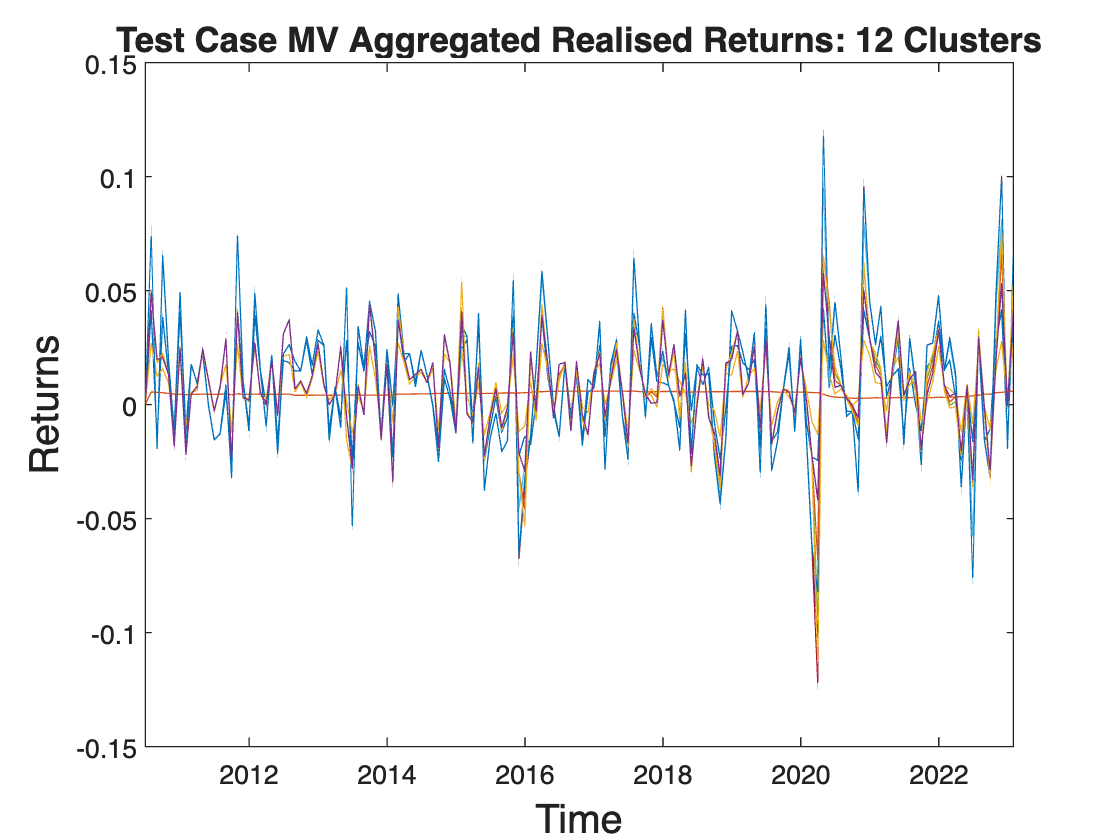

% Assuming myTimetable is your timetable object
figure; % Create a new figure

myTimetable = TC_HRP_Rewted_Cluster_RealisedRet_TT;

% Iterate through each variable in the timetable
for i = 1:width(myTimetable)
    plot(myTimetable.Time, myTimetable{:, i});
    
    % Customize the plot, e.g., set labels, titles, etc.
   title(['Test Case MV Aggregated Realised Returns: ',num2str(width(myTimetable)), ' Clusters'],'FontSize', 13);
    xlabel('Time','FontSize', 15);
    ylabel('Returns','FontSize', 15);
    hold on; % Hold for overlaying plots
end